# Entire story of the paper

## Only attention: L2/3 WTA

clear;
clc;
addpath('../funcs');
load ../../data/all4000_onlyAttn_0_0.5_0_0.05_Iattn_0.02.mat;
meanSheet = meanSheet*1000;
% envSheet = envSheet*1000;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 10;
steps = size(meanSheet,1);

## rule out unstable oscillation

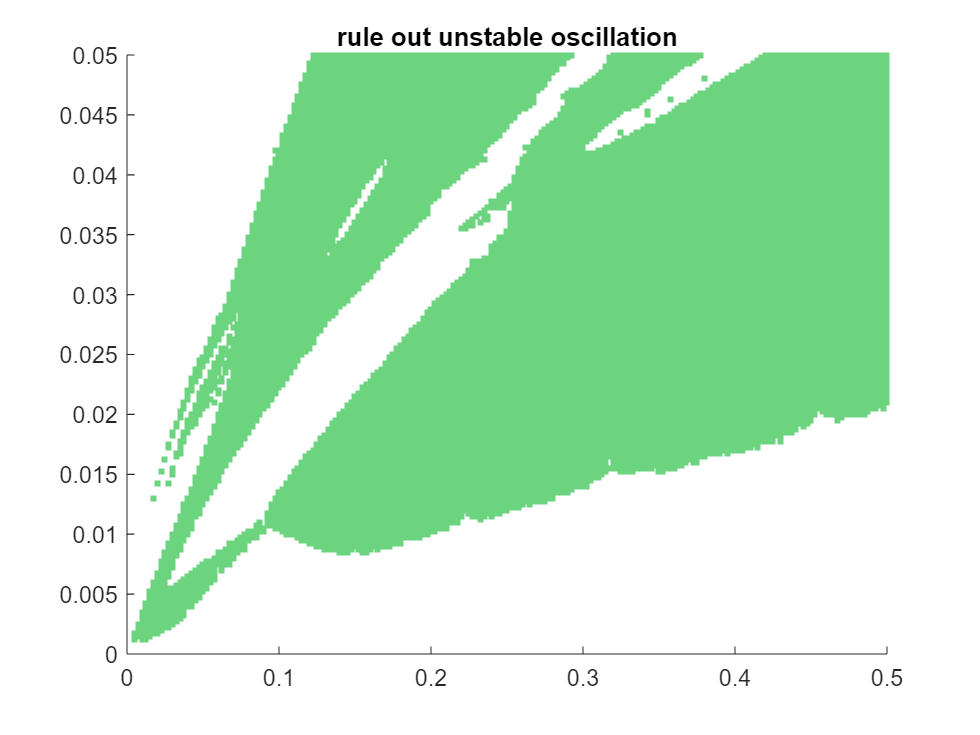

ruleOut = zeros(steps,steps);
maxPks = 5;

for i = 1:steps
    for j = 1:steps
        cond4 = squeeze(psdPeaksSheet(i,j,:,5)); cond5 = squeeze(psdPeaksSheet(i,j,:,6));
        tmp = max([cond4; cond5]);
        if tmp<=maxPks && tmp>=1 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("rule out unstable oscillation");

## Attention only WTA

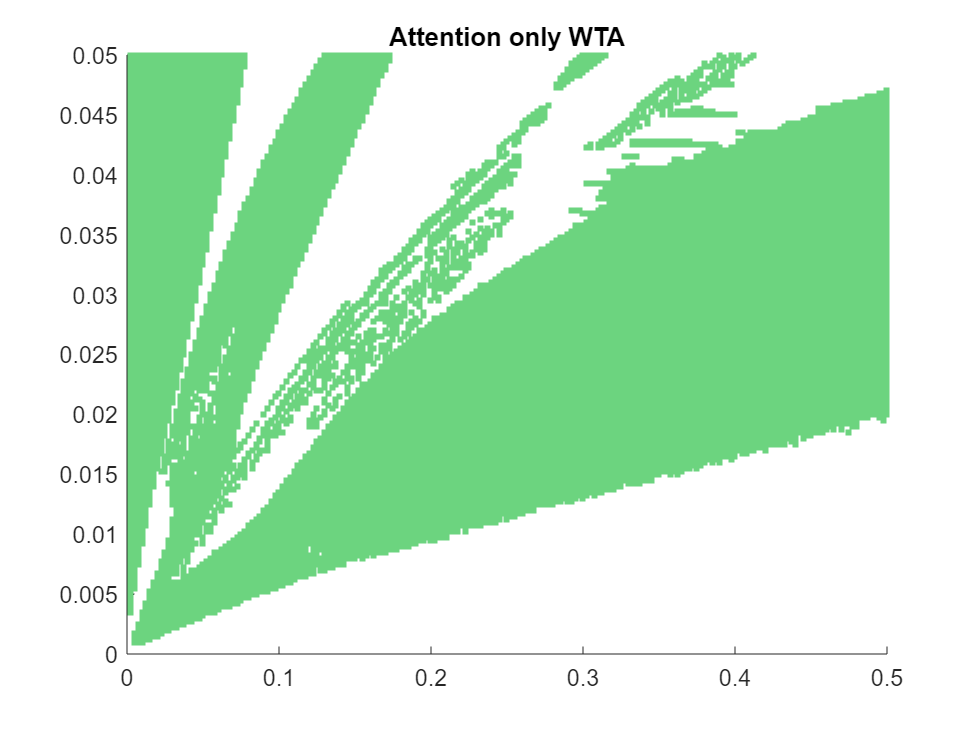

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = meanSheet(i,j,pop,1); cond1 = meanSheet(i,j,pop,2); cond2 = meanSheet(i,j,pop,3);
        cond3 = meanSheet(i,j,pop,4); cond4 = meanSheet(i,j,pop,5); cond5 = meanSheet(i,j,pop,6);
        if cond4>cond5
            WTA(i,j) = 1;

        end
    end
end

WTA = WTA == 1;

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Attention only WTA");

## combine: rule our unstable oscillation + attention only WTA

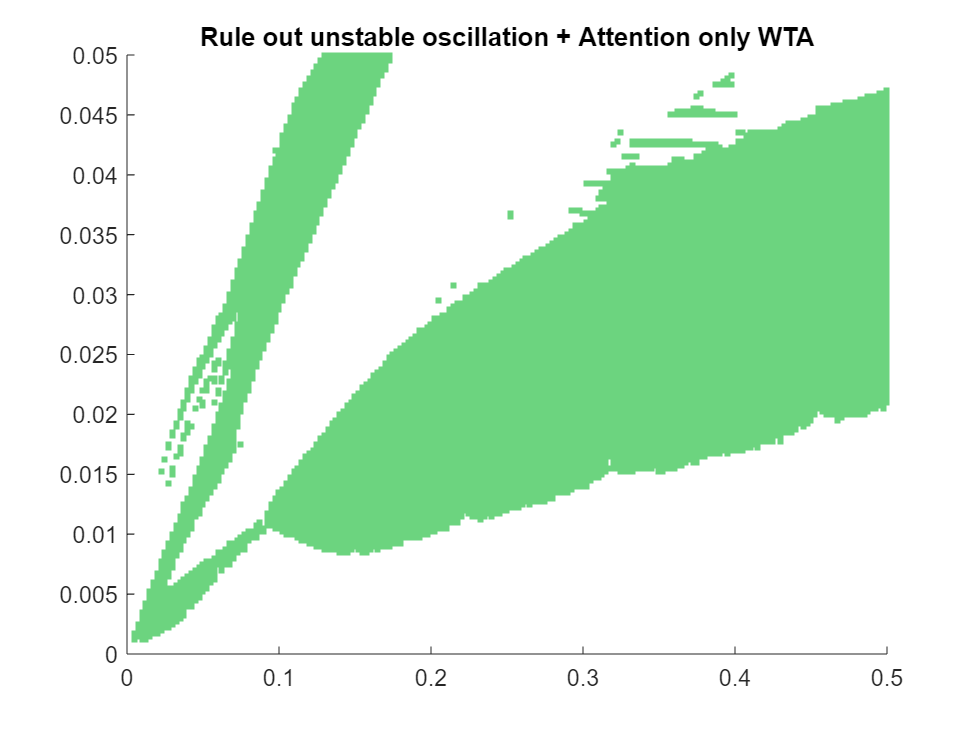

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = meanSheet(i,j,pop,1); cond1 = meanSheet(i,j,pop,2); cond2 = meanSheet(i,j,pop,3);
        cond3 = meanSheet(i,j,pop,4); cond4 = meanSheet(i,j,pop,5); cond5 = meanSheet(i,j,pop,6);
        if cond4>cond5
            WTA(i,j) = 1;
        end
    end
end

WTA = WTA == 1;
WTA = and(WTA,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Rule out unstable oscillation + Attention only WTA");

## Sensory + attention: L2/3 antiWTA

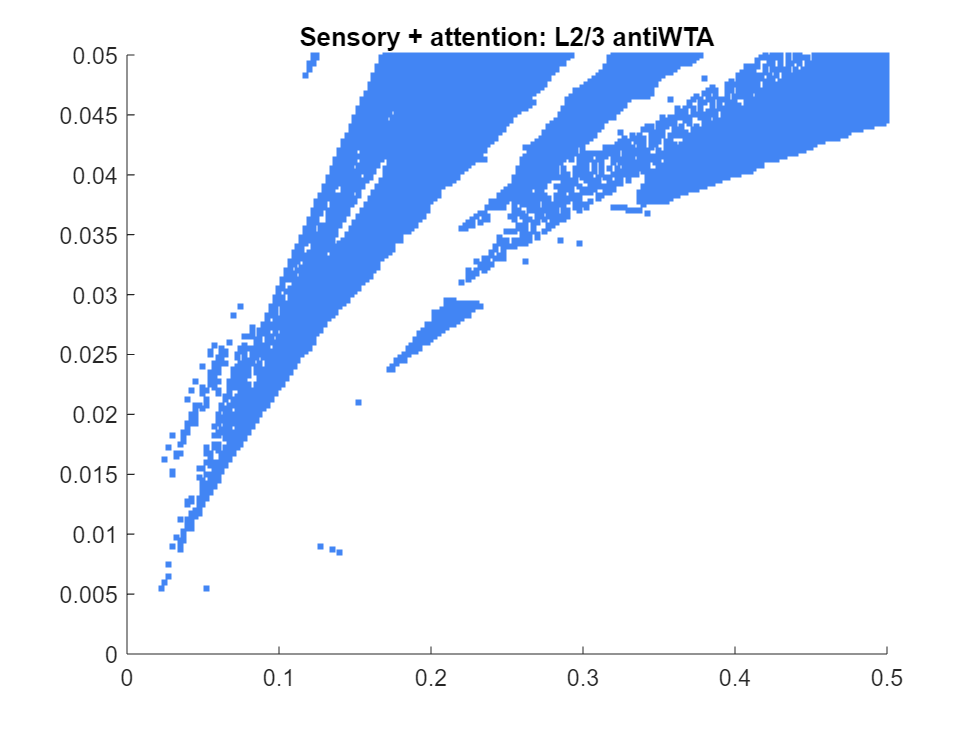

load ../../data/all5000_levelMethod2_0_0.5_0_0.05_Iattn_0.02.mat;
pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;
antiWTA = and(antiWTA,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Sensory + attention: L2/3 antiWTA");

## combine above all

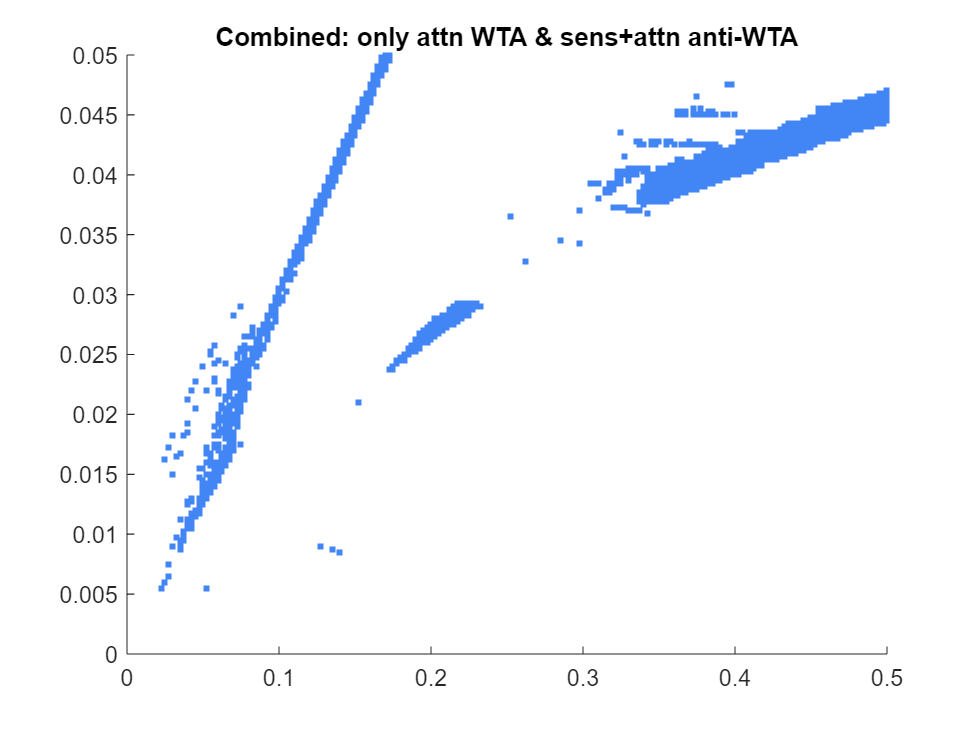

antiWTA = and(WTA,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Combined: only attn WTA & sens+attn anti-WTA");

## Sensory + attention: L5 in order

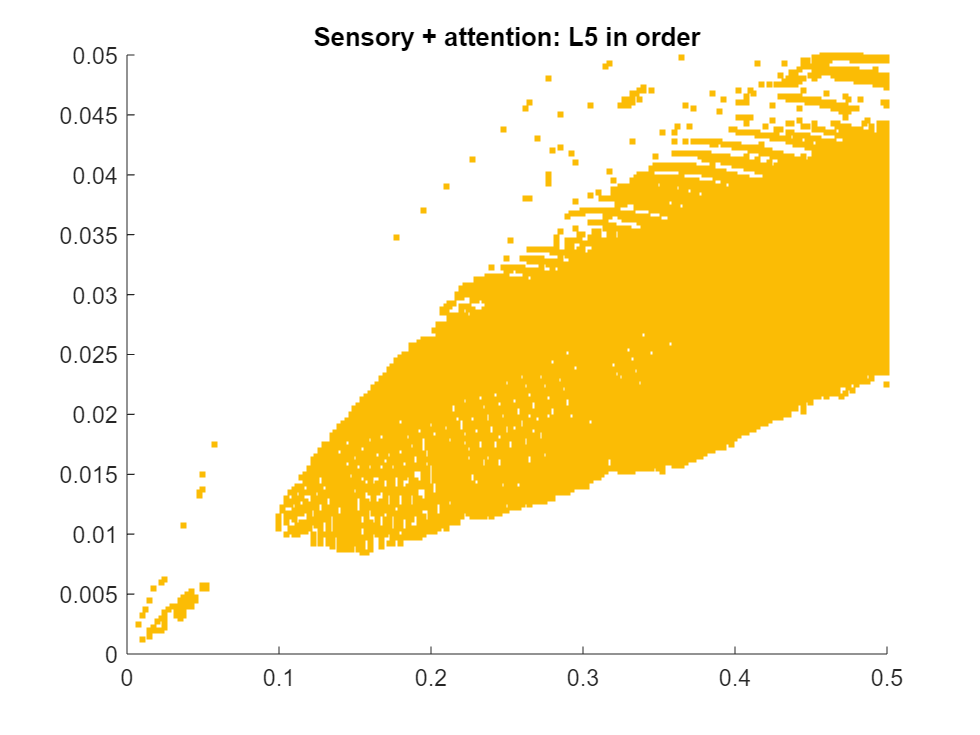

load ../../data/all5000_levelMethod2_0_0.5_0_0.05_Iattn_0.02.mat;
pop = 5;
order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

order = order == 1;
order = and(order,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Sensory + attention: L5 in order");

## combine above all

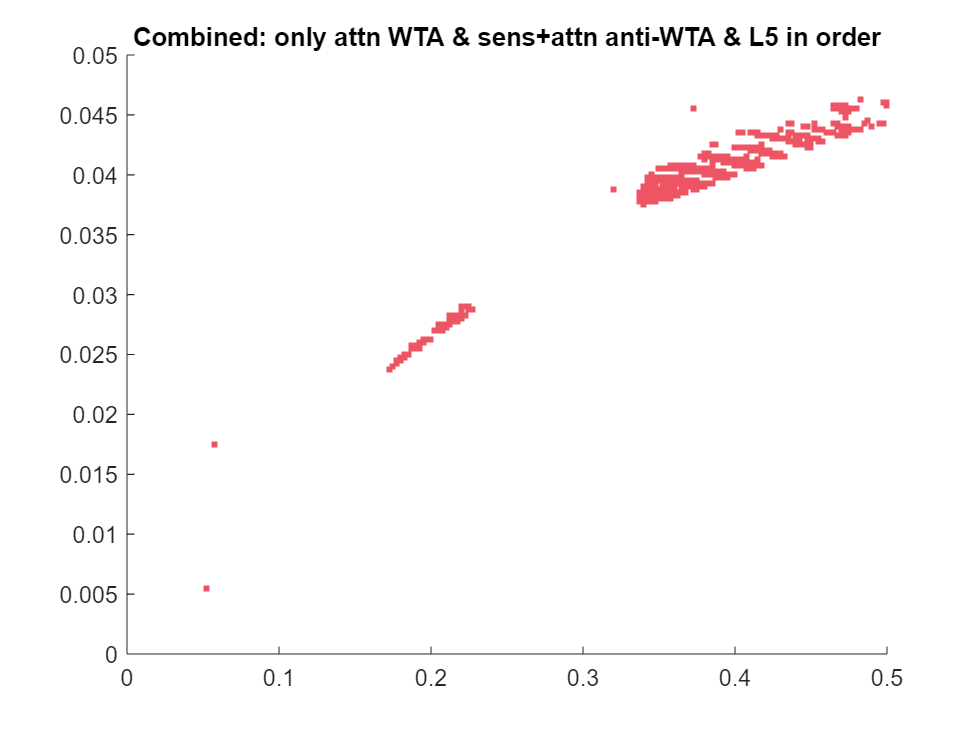

order = and(order,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ED5564"); % red
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Combined: only attn WTA & sens+attn anti-WTA & L5 in order");